clear;clc;close all;
global settings;

## DQPSK调制

TransmitterSettings;%% DQPSK预编码
DataSeq_x=randi([0 1],1,settings.NumOfBit);
data=DataSeq_x';
figure;
[x_seq_I,x_seq_Q]=Precoder(DataSeq_x,settings.NumOfBit);


## 电脉冲成形（升余弦）

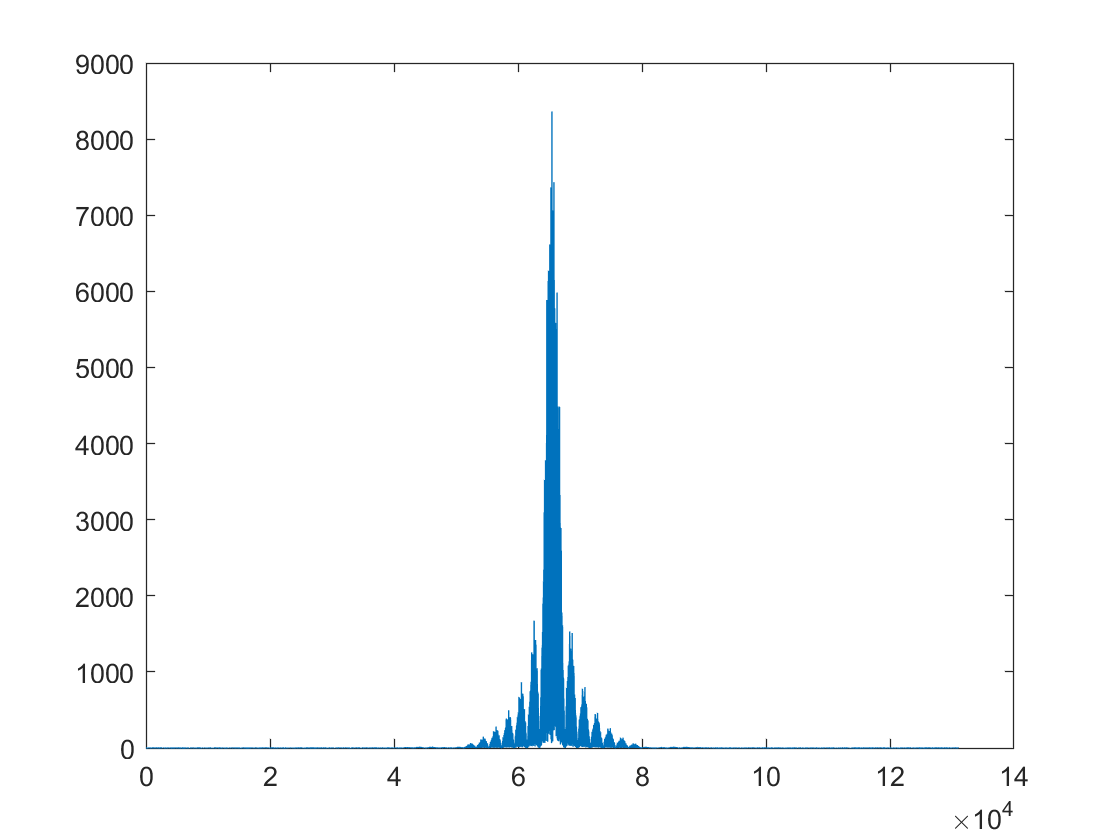

elecx_i= ElecPulseShaping(-(2*x_seq_I-1),settings.Duty,settings.Roll);
elecx_q= ElecPulseShaping(-(2*x_seq_Q-1),settings.Duty,settings.Roll);
elecx_i=elecx_i/sqrt(mean(abs(elecx_i).^2));%功率归一化
elecx_q=elecx_q/sqrt(mean(abs(elecx_q).^2));%功率归一化
Eout=(elecx_i+1i*elecx_q)/sqrt(2);
figure;
plot(fftshift(abs(fft(Eout))));

## 光纤信道传输

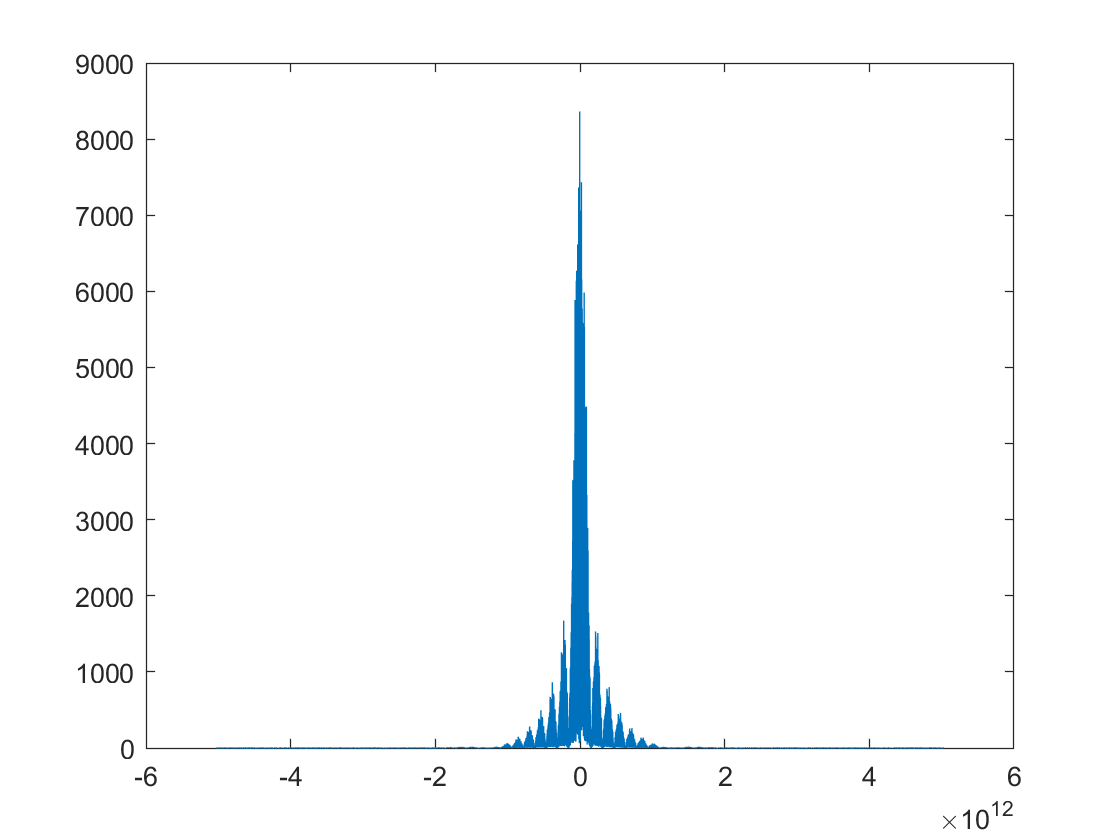

beta2=-settings.FiberChromaticDispersion*(settings.Lam^2)/(2*pi*settings.Light)*10^(-21);
H=exp(1i/2*beta2.*settings.w.^2*settings.FiberLength);
%H=1;
U_fft(:,1)=fftshift(fft(Eout));

U(:,1)=H.*U_fft(:,1);
a_out=ifft(ifftshift(U)); %频域色散

plot(settings.w,ifftshift(abs(fft(a_out))));

## 采样精度为8个Bits,每个符号1个采样点

settings.applyadc=1;                               
settings.adcbits=8;                               
settings.OversamplingFactor=1;      
DecimationRate=settings.Nt/settings.OversamplingFactor;
Irxdec = [ decimate( real(a_out), DecimationRate,16,'fir' ) ...
           decimate( imag(a_out), DecimationRate,16,'fir' )  ];
       
    if settings.applyadc
    M = max( max( abs( Irxdec ) ) );   % <- Optimal range. There's no loss.
    Irxdec = round( ( Irxdec + M ) / 2 ./ M * 2^settings.adcbits )* 2 .* M / 2^settings.adcbits - M;
    end
Signals = complex( Irxdec(:,1), Irxdec(:,2) );
R_c_x= transpose(Signals(:,1));


Irxdec = [ decimate( real(Eout), DecimationRate,16,'fir' ) ...
           decimate( imag(Eout), DecimationRate,16,'fir' )  ];
       
    if settings.applyadc
    M = max( max( abs( Irxdec ) ) );   % <- Optimal range. There's no loss.
    Irxdec = round( ( Irxdec + M ) / 2 ./ M * 2^settings.adcbits )* 2 .* M / 2^settings.adcbits - M;
    end
Signals = complex( Irxdec(:,1), Irxdec(:,2) );
TestRcx= transpose(Signals(:,1));


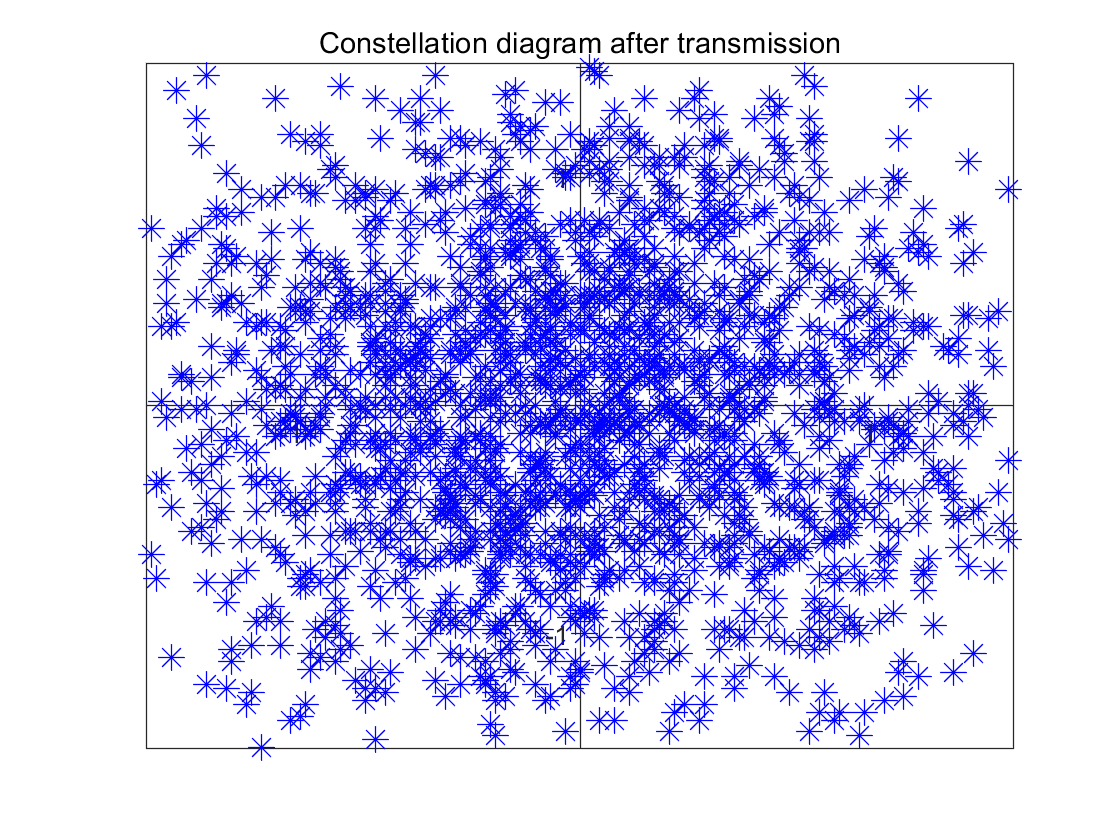

figure
plot(real(R_c_x),imag(R_c_x),'b*','Markersize',10);
title("Constellation diagram after transmission");

axis([-1.5 1.5 -1.5 1.5]);
set(gca,'YAxisLocation','origin');
set(gca,'XAxisLocation','origin');
set(gca,'XTick',-1:1:1);
set(gca,'YTick',-1:1:1);

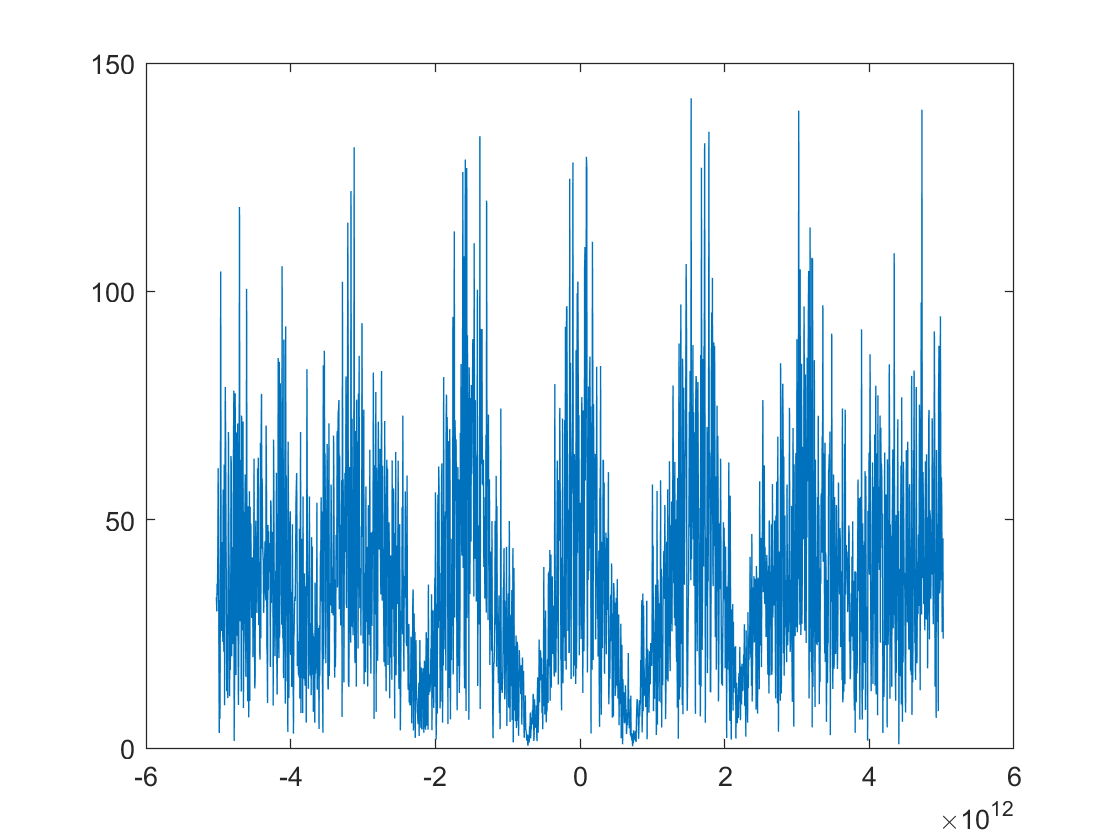

w = decimate( settings.w, DecimationRate,16,'fir');
plot(w,abs(fft(R_c_x)));

[numiin,numqin,erriin,errqin,xiin,xqin,inelecx_i,inelecx_q]=CalErrCode(R_c_x,x_seq_I,x_seq_Q);

## **Optical Compensation**

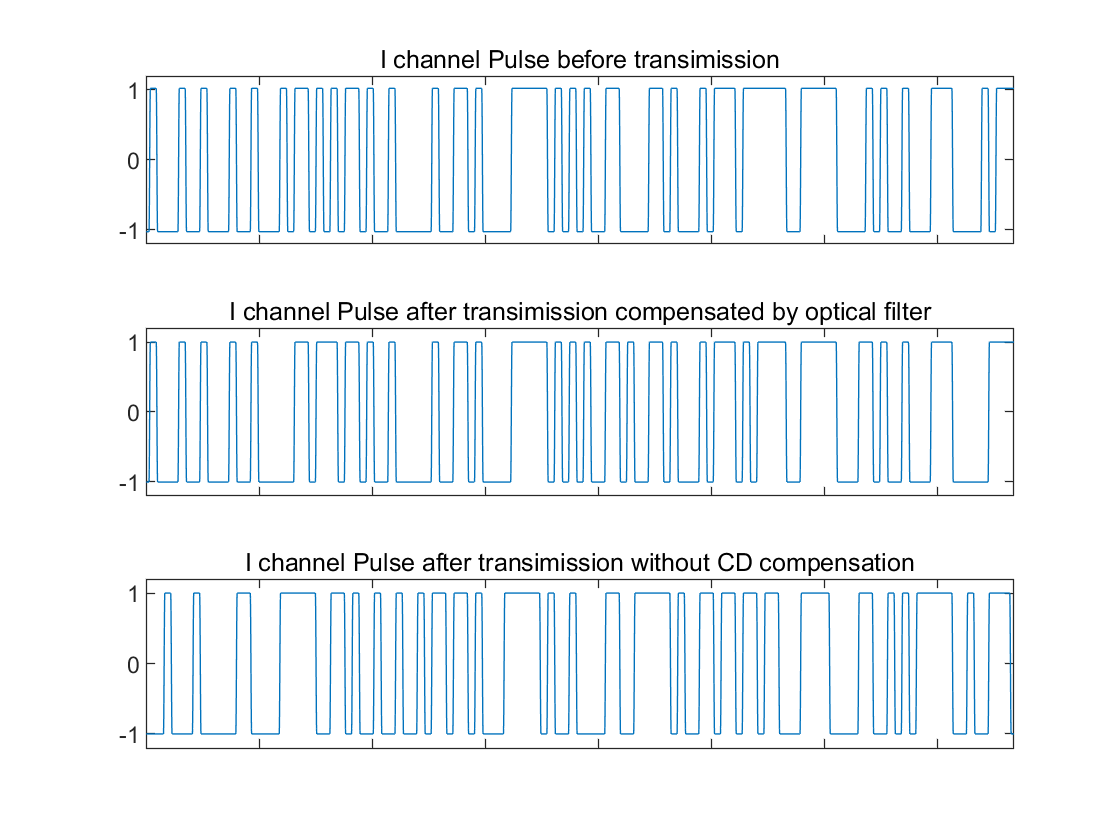

T_c_x = CDComOF(R_c_x);
[numiof,numqof,erriof,errqof,xiof,xqof,ofelecx_i,ofelecx_q]=CalErrCode(T_c_x,x_seq_I,x_seq_Q);
figure;
subplot(3,1,1);
plot(elecx_i(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse before transimission');
subplot(3,1,2);
plot(ofelecx_i(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse after transimission compensated by optical filter');
subplot(3,1,3);
plot(inelecx_i(1:64*120));
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse after transimission without CD compensation');

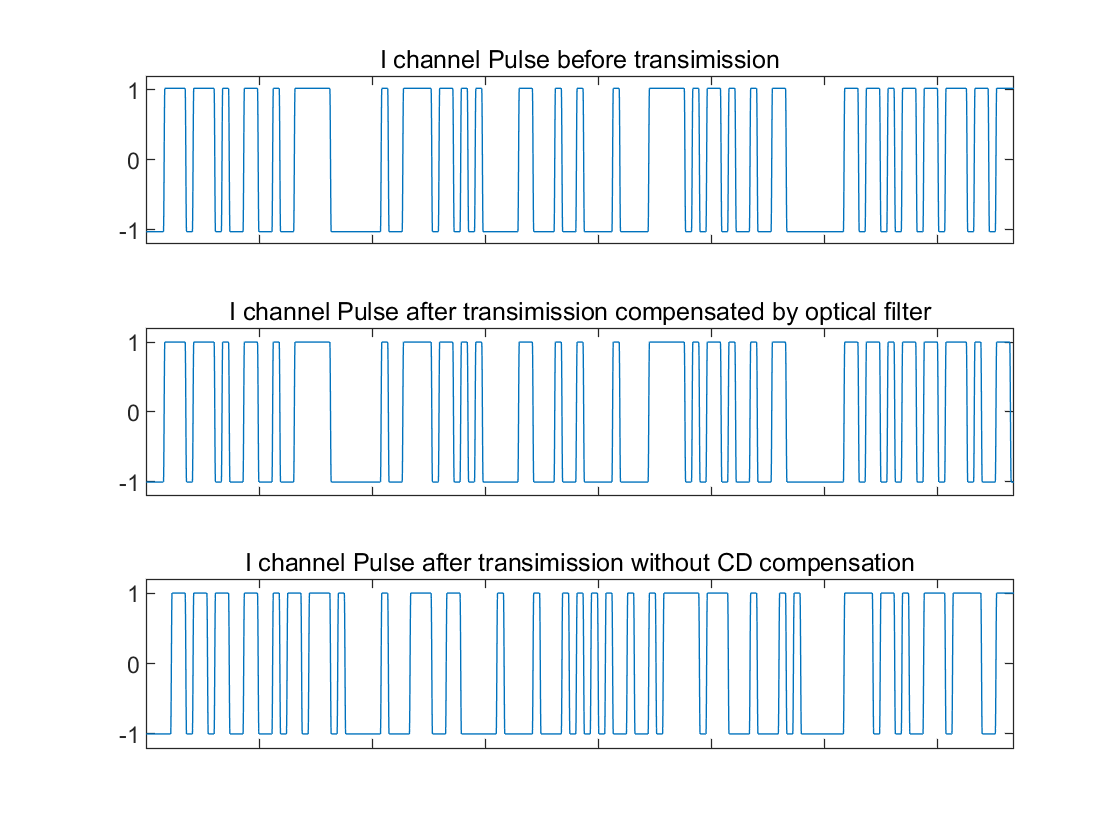

figure;
subplot(3,1,1);
plot(elecx_q(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse before transimission');
subplot(3,1,2);
plot(ofelecx_q(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse after transimission compensated by optical filter');
subplot(3,1,3);
plot(inelecx_q(1:64*120));
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse after transimission without CD compensation');

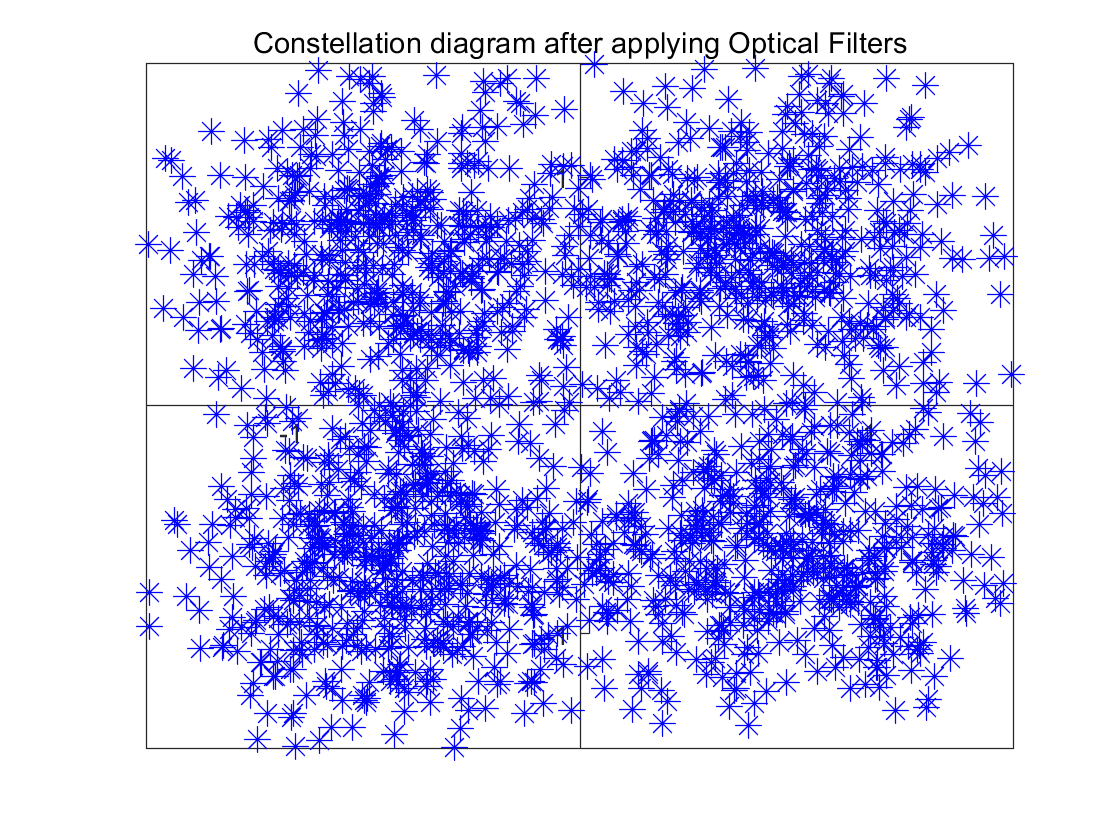

figure;
plot(real(T_c_x),imag(T_c_x),'b*','Markersize',10);
title('Constellation diagram after applying Optical Filters');
axis([-1.5 1.5 -1.5 1.5]);
set(gca,'YAxisLocation','origin');
set(gca,'XAxisLocation','origin');
set(gca,'XTick',-1:1:1);
set(gca,'YTick',-1:1:1);

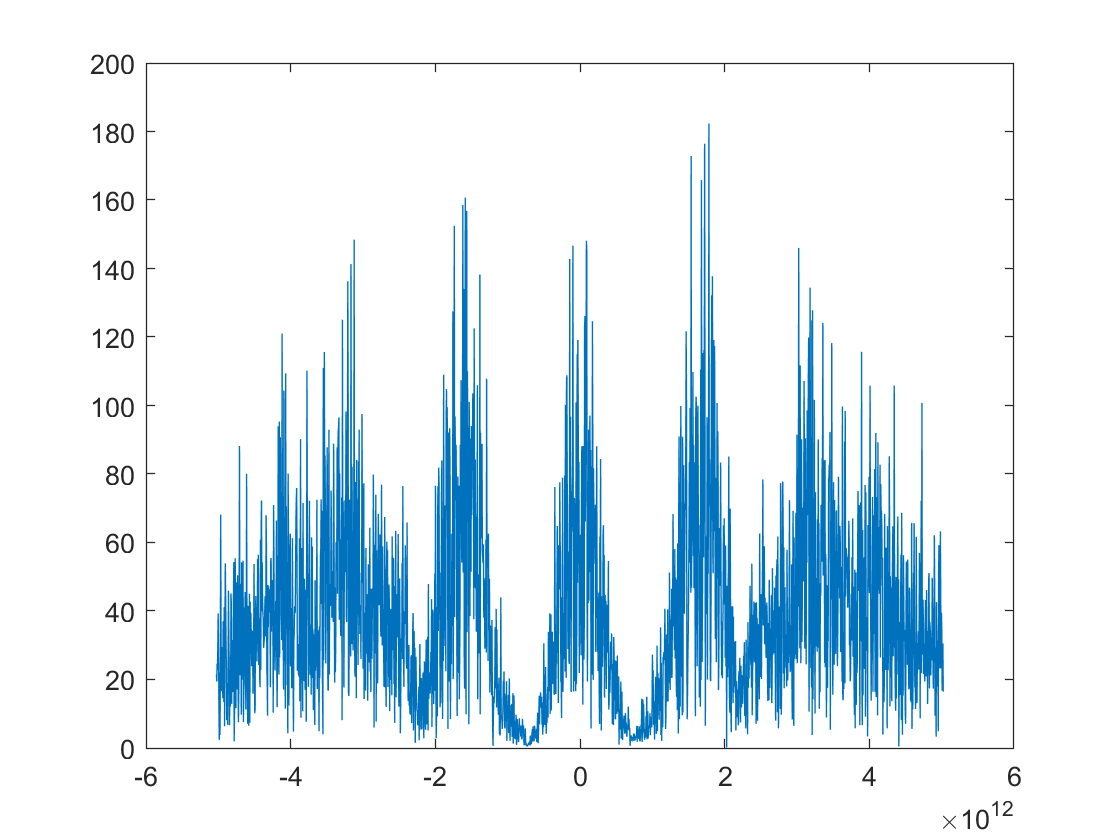

plot(w,abs(fft(T_c_x)));

## DCF Compensation

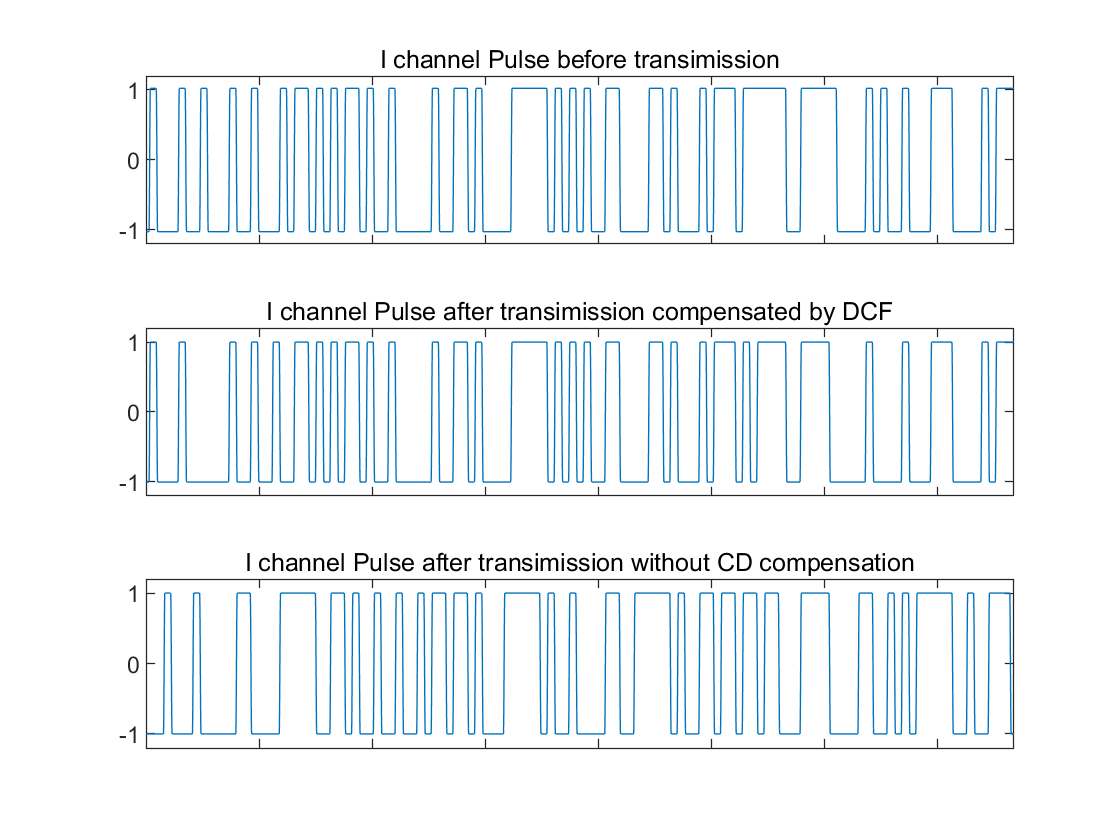

Tcx = CDComDCF(R_c_x); 
[numidcf,numqdcf,erridcf,errqdcf,xidcf,xqdcf,dcfelecx_i,dcfelecx_q]=CalErrCode(Tcx,x_seq_I,x_seq_Q);
figure;
subplot(3,1,1);
plot(elecx_i(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse before transimission');
subplot(3,1,2);
plot(dcfelecx_i(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse after transimission compensated by DCF');
subplot(3,1,3);
plot(inelecx_i(1:64*120));
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('I channel Pulse after transimission without CD compensation');

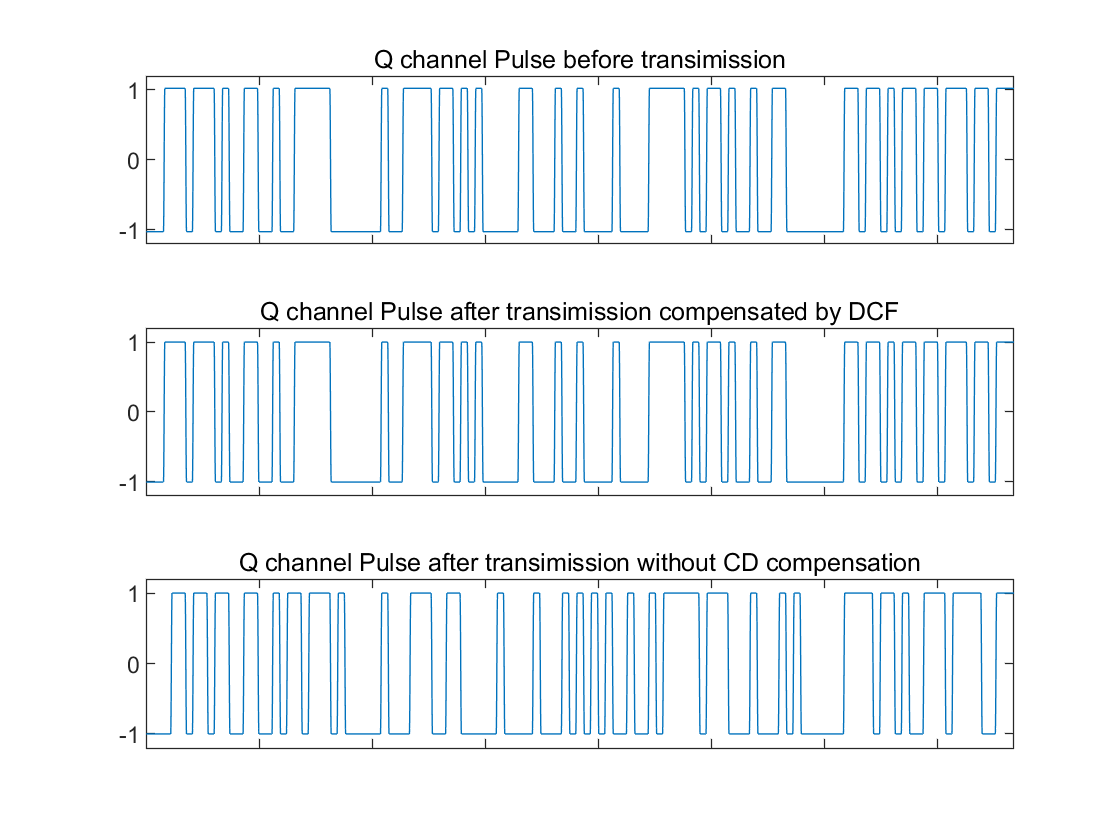

figure;
subplot(3,1,1);
plot(elecx_q(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('Q channel Pulse before transimission');
subplot(3,1,2);
plot(dcfelecx_q(1:64*120));hold on;
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('Q channel Pulse after transimission compensated by DCF');
subplot(3,1,3);
plot(inelecx_q(1:64*120));
axis([0 64*120 -1.2 1.2]);
set(gca,'XTickLabel','')
title('Q channel Pulse after transimission without CD compensation');

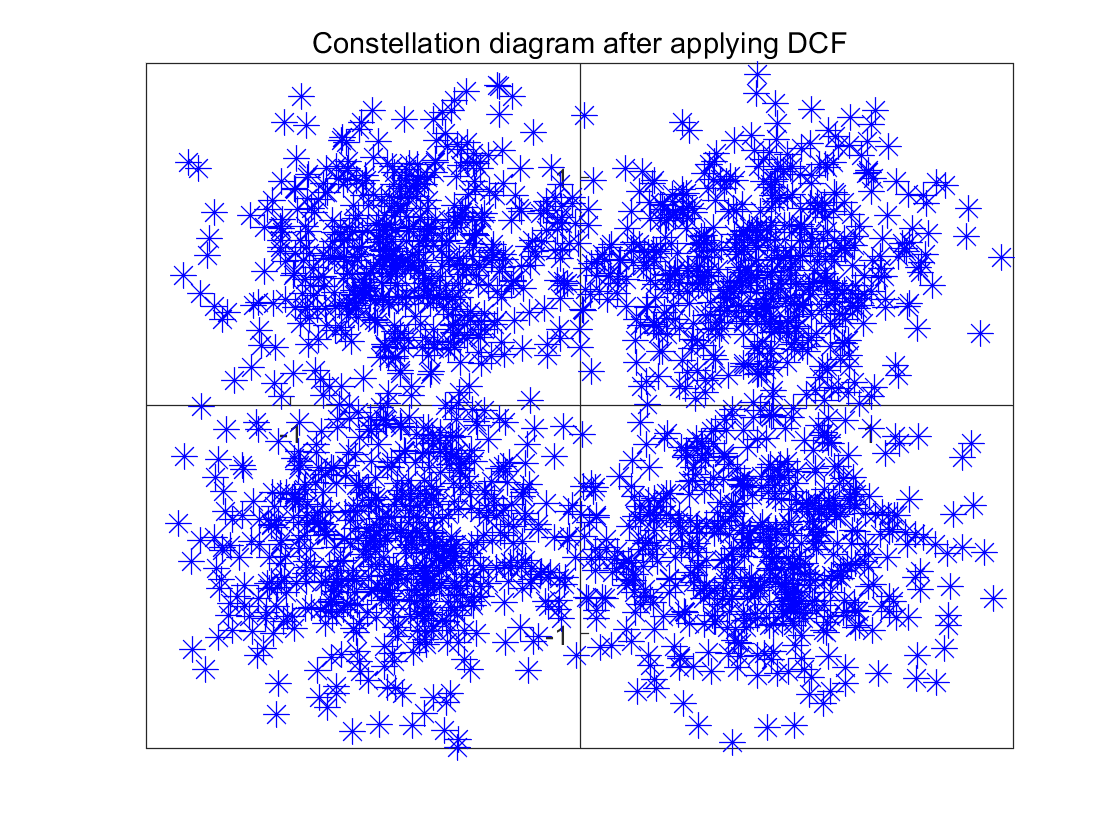

figure;

figure
plot(real(Tcx),imag(Tcx),'b*','Markersize',10);
title('Constellation diagram after applying DCF');
axis([-1.5 1.5 -1.5 1.5]);
set(gca,'YAxisLocation','origin');
set(gca,'XAxisLocation','origin');
set(gca,'XTick',-1:1:1);
set(gca,'YTick',-1:1:1);

plot(w,abs(fft(Tcx)));

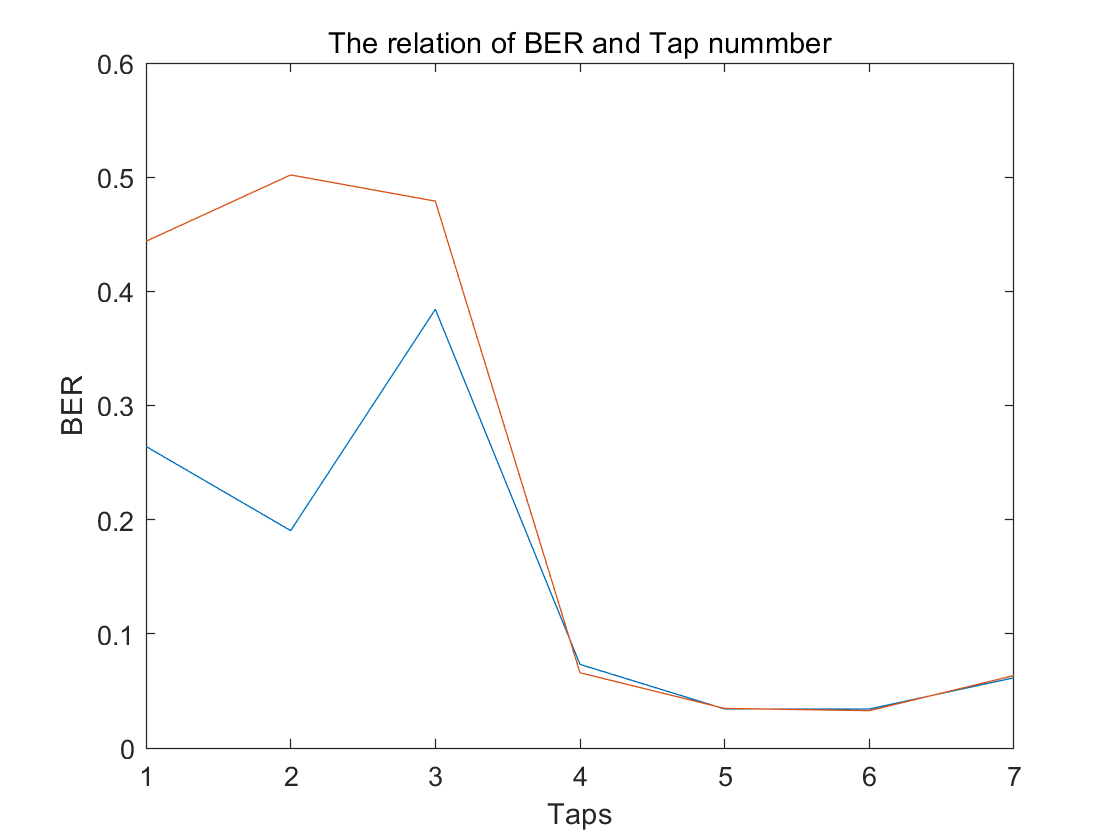


T_c_x=testTap(R_c_x,x_seq_I,x_seq_Q);